%%% tese the parameter of our methed
clear;
a0=0:0.1:3;
s=-0.5;
samerror=zeros(length(a0),1);%样本点误差
testerror=zeros(length(a0),1);%测试点误差
meanerror=testerror;




% 生成插值点集
X = -1:0.1:1;
F = zeros(1,length(X));

for i=1:length(X)
    F(i) = 1/(1+25*X(i)*X(i));
end


% 生成拟合点集
step = 0.01;
x = -1:step:1;
f = zeros(1,length(x));

for i=1:length(x)
    f(i) = 1/(1+25*x(i)*x(i));
end

phi = zeros(1,length(X));
r = zeros(1,length(X));
P = zeros(1,length(x));
Q= zeros(1,length(X));
rhoi=0.25;
for k=1:length(a0)
    a = a0(k)*ones(1,length(X));
    for j = 1:length(x)
        for i = 1: length(X)
            if a(i)<1e-7 && abs(x(j)-X(i))<1e-7
                phi = zeros(1,length(X));
                phi(i) = 1;
                break;
            end
            r(i) = abs(x(j)-X(i))./rhoi;
            if r(i)>1
                phi(i) = 0;
                continue
            end
            phi(i) = ((1-r(i)).^4)*(4*r(i)+1)*((a(i)+(r(i).^2)./2).^s/2+2*(a(i)+r(i).^2).^s);
        end
        P(j) = (F*phi')/sum(phi);
        for i=1:length(X)
            if(abs(x(j)-X(i))<1e-7)
                Q(i)=P(j);
            end
        end
    end

    testerror(k)=(max(abs(f-P)));
    meanerror(k)=(mean(abs(f-P)));
    samerror(k)=(max(abs(F-Q)));
end

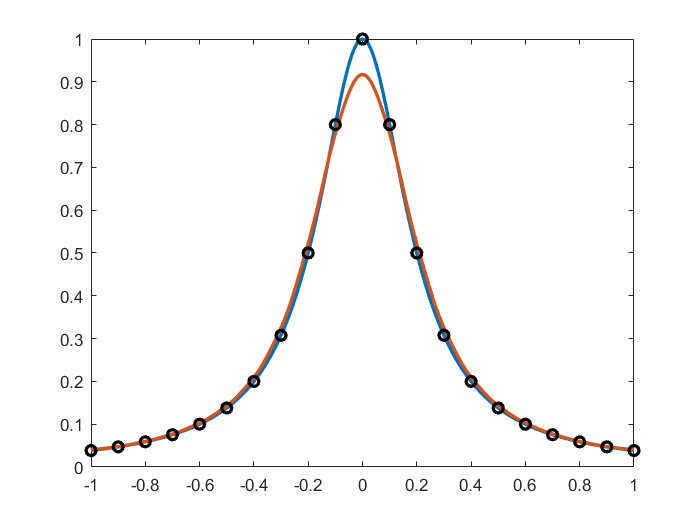

plot(x,f,x,P, 'linewidth', 2);
hold on;
scatter(X,F,'ok', 'linewidth', 2);
hold off;

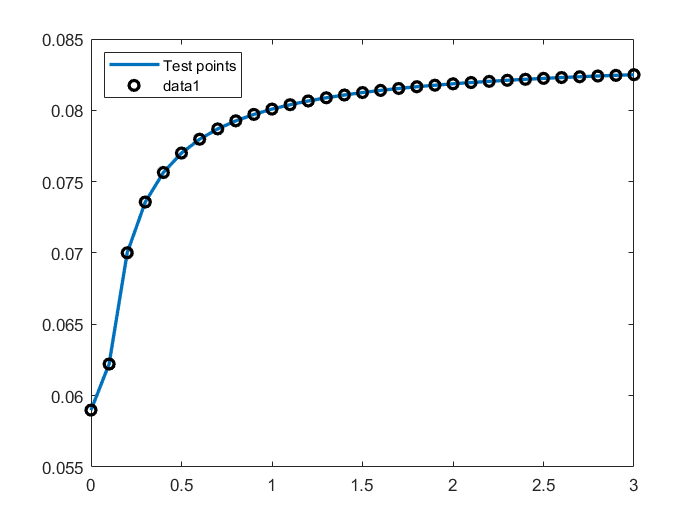

plot(a0,testerror, 'linewidth', 2);
hold on;
legend('Test points','Location','northwest')
scatter(a0,testerror,'ok', 'linewidth', 2);
hold off;